
T = readtable("dataT.xlsx");

%钻深
bit_depth=table2array(T(:,1));
%钻压
WOB=table2array(T(:,2));
%井眼深度
hole_depth=table2array(T(:,3));
%流速
f=table2array(T(:,4));
%立管压力
psi=table2array(T(:,5));
%扭矩
torque=table2array(T(:,6));
%流速井深
fh=table2array(T(:,8));
%流速平方
f2=table2array(T(:,9));
data = [psi,fh,f2,f,bit_depth,hole_depth,torque,WOB];
R = corrcoef(data)

R =     1.0000    0.9909    0.8779    0.8539    0.6279    0.6211    0.2980    0.3254
    0.9909    1.0000    0.8813    0.8479    0.6289    0.6224    0.2767    0.3436
    0.8779    0.8813    1.0000    0.9760    0.2284    0.2187    0.0415    0.3737
    0.8539    0.8479    0.9760    1.0000    0.2079    0.1990    0.0709    0.3131
    0.6279    0.6289    0.2284    0.2079    1.0000    0.9998    0.5695    0.0905
    0.6211    0.6224    0.2187    0.1990    0.9998    1.0000    0.5705    0.0836
    0.2980    0.2767    0.0415    0.0709    0.5695    0.5705    1.0000    0.0015
    0.3254    0.3436    0.3737    0.3131    0.0905    0.0836    0.0015    1.0000


CMP=corrMatPlot(R,'Format','triu','Type','ssq');

  @author : slandarer
  gzh  : slandarer随笔

    corrMatPlot 的文档



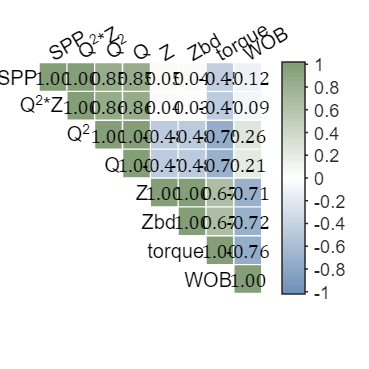

ans =   corrMatPlot - 属性:

             ax: [1×1 Axes]
          drawn: 1
      arginList: {'Labels'  'colorMap'  'Format'  'Type'}
         Labels: {'class 1'  'class 2'  'class 3'  'class 4'  'class 5'  'class 6'  'class 7'  'class 8'}
       colorMap: [3×3 double]
         baseCM: {[3×3 double]  [3×3 double]  [3×3 double]  [3×3 double]  [5×3 double]  [3×3 double]}
         Format: 'triu'
           Type: 'ssq'
          XData: [8×8 double]
            num: 8
        corrMat: [8×8 double]
         boxHdl: [1×1 Line]
         txtHdl: []
      RLabelHdl: [6.1035e-04 1.0006 2.0004 3.0002 10.0005 11.0005 12.0005 13.0005]
      CLabelHdl: [14.0005 15.0005 16.0005 17.0005 18.0005 19.0005 20.0005 21.0005]
    colorbarHdl: [1×1 ColorBar]
      matrixHdl: [8×8 struct]


cList=[114,146,184;255,255,255;132,158,119]./255;
CMP=CMP.setColorMap(cList);
CMP=CMP.draw();
CMP.setLabelStr({'SPP','Q^2*Z','Q^2','Q','Z','Zbd','torque','WOB'});
CMP.setCorrTxt('Color',[0,0,0],'FontName','Cambria','FontSize',12)